Analaysis

% housekeeping

% add folder with helper function tp to path
function_folder = fullfile(pwd, 'functions', filesep);
addpath(genpath(function_folder))

d = struct;
cfg = struct;

% get subject numbers
cfg.exp_name = 'gazeCon'; % 'free' or 'gazeCon'
if strcmp(cfg.exp_name, 'free')
    cfg.subNums = 4:37;
elseif strcmp(cfg.exp_name, 'gazeCon')
    cfg.subNums = [102:108, 110:136];
end
cfg.n = length(cfg.subNums);

% other standard configurations
cfg.categories = {'bathroom', 'kitchen'};
cfg.colormaps = load('white_zero_colormap.mat');
cfg.FontName = 'Helvetica';
cfg.FontSize = 15;


% load images and get DNN representation
cfg.analysis_names = {'typical', 'control', 'typical_raw', 'control_raw'}

cfg = struct with fields:
          exp_name: 'gazeCon'
           subNums: [102 103 104 105 106 107 108 110 111 112 113 114 115 116 117 118 119 120 121 122 123 124 125 126 127 128 129 130 131 132 133 134 135 136]
                 n: 34
        categories: {'bathroom'  'kitchen'}
         colormaps: [1×1 struct]
          FontName: 'Helvetica'
          FontSize: 15
    analysis_names: {'typical'  'control'  'typical_raw'  'control_raw'}


images = load_images(cfg);

Loaded image: 102_bath1_3D.png
Loaded image: 102_bath2_3D.png
Loaded image: 102_bath3_3D.png
Loaded image: 103_bath1_3D.png
Loaded image: 103_bath2_3D.png
Loaded image: 103_bath3_3D.png
Loaded image: 104_bath1_3D.png
Loaded image: 104_bath2_3D.png
Loaded image: 104_bath3_3D.png
Loaded image: 105_bath1_3D.png
Loaded image: 105_bath2_3D.png
Loaded image: 105_bath3_3D.png
Loaded image: 106_bath1_3D.png
Loaded image: 106_bath2_3D.png
Loaded image: 106_bath3_3D.png
Loaded image: 107_bath1_3D.png
Loaded image: 107_bath2_3D.png
Loaded image: 107_bath3_3D.png
Loaded image: 108_bath1_3D.png
Loaded image: 108_bath2_3D.png
Loaded image: 108_bath3_3D.png
Loaded image: 110_bath1_3D.png
Loaded image: 110_bath2_3D.png
Loaded image: 110_bath3_3D.png
Loaded image: 111_bath1_3D.png
Loaded image: 111_bath2_3D.png
Loaded image: 111_bath3_3D.png
Loaded image: 112_bath1_3D.png
Loaded image: 112_bath2_3D.png
Loaded image: 112_bath3_3D.png
Loaded image: 113_bath1_3D.png
Loaded image: 113_bath2_3D.png
Loaded i


% typical images (draw3D)
cfg.analysis_name = 'typical';
[d, cfg] = get_dnn_layer_similarity(d, images, cfg);

analysis typical - layer #1 - category: bathroom
analysis typical - layer #1 - category: kitchen



% control images (draw3D)
cfg.analysis_name = 'control';
[d, cfg] = get_dnn_layer_similarity(d, images, cfg);

analysis control - layer #1 - category: bathroom
analysis control - layer #1 - category: kitchen


analysis typical_raw - layer #1 - category: bathroom
analysis typical_raw - layer #1 - category: kitchen


analysis control_raw - layer #1 - category: bathroom
analysis control_raw - layer #1 - category: kitchen


Gaze

cfg.force_recompute = false; % set to true to reproduce analysis

%a_preprocessing(cfg)
%cfg.minFixDur = 100;
%b_detFix(cfg)
%c_showFix % only for visualization of fixations (not part of analysis)
%d_AOIfix(cfg)

cfg.minNumPerCate = 10;
cfg.cutFirstFix = false;
e_getGazePatterns(cfg);

Subject 102 already exists
Subject 103 already exists
Subject 104 already exists
Subject 105 already exists
Subject 106 already exists
Subject 107 already exists
Subject 108 already exists
Subject 110 already exists
Subject 111 already exists
Subject 112 already exists
Subject 113 already exists
Subject 114 already exists
Subject 115 already exists
Subject 116 already exists
Subject 117 already exists
Subject 118 already exists
Subject 119 already exists
Subject 120 already exists
Subject 121 already exists
Subject 122 already exists
Subject 123 already exists
Subject 124 already exists
Subject 125 already exists
Subject 126 already exists
Subject 127 already exists
Subject 128 already exists
Subject 129 already exists
Subject 130 already exists
Subject 131 already exists
Subject 132 already exists
Subject 133 already exists
Subject 134 already exists
Subject 135 already exists
Subject 136 already exists
Subject 102 already exists
Subject 103 already exists
Subject 104 already exists
S

%e_getGazePatterns_firstFix(cfg);

cfg.variables_of_interest = {'ObjectFixCount',...
    'ObjectDwellsCate', 'ObjectDwellsCateEven', 'ObjectDwellsCateOdd',...
    'ObjectDwellsCateEarly', 'ObjectDwellsCateLate',...
    'ObjectCatePrio', 'ObjectCatePrioOdd', 'ObjectCatePrioEven', ...
    'ObjectCatePrioEarly', 'ObjectCatePrioLate'};
d = makeGDM(d, cfg);
%d = regressOutMean(d, cfg);


Get inter-subject correlation

Plotting and saving inter-subject RDM for task:ObjectFixCount and bathroom
Plotting and saving inter-subject RDM for task:ObjectDwellsCate and bathroom
Plotting and saving inter-subject RDM for task:ObjectDwellsCateEven and bathroom
Plotting and saving inter-subject RDM for task:ObjectDwellsCateOdd and bathroom
Plotting and saving inter-subject RDM for task:ObjectDwellsCateEarly and bathroom
Plotting and saving inter-subject RDM for task:ObjectDwellsCateLate and bathroom
Plotting and saving inter-subject RDM for task:ObjectCatePrio and bathroom
Plotting and saving inter-subject RDM for task:ObjectCatePrioOdd and bathroom
Plotting and saving inter-subject RDM for task:ObjectCatePrioEven and bathroom
Plotting and saving inter-subject RDM for task:ObjectCatePrioEarly and bathroom
Plotting and saving inter-subject RDM for task:ObjectCatePrioLate and bathroom
Plotting and saving inter-subject RDM for task:ObjectFixCount and kitchen
Plotting and saving inter-subject RDM for task:ObjectDwells

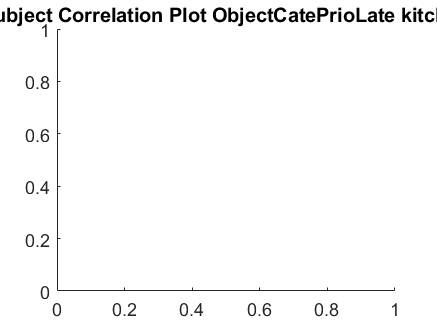

Compare categories


cfg.regressOutMean = false;
cfg.correlation_type = 'spearman';
d = intersub_cor(d, cfg);

Get gaze distance

d = getGazeDist(d, cfg);

Data exist already


Split half correlation

% split half correlation
cfg.regressOutMean = false;
cfg.variables_of_interest = {'MannanDist', 'ObjectFixCount',...
    'ObjectDwellsCate', 'ObjectCatePrio'};
cfg.correlation_type = 'pearson';
cfg.permutation_test = true;
cfg.n_permutations = 10;
d = getSpliHalfReliability(d, cfg);

 
Fixation count
r: 0.26411, p = 2.0889e-10
10% of permutations of is done
20% of permutations of is done
30% of permutations of is done
40% of permutations of is done
50% of permutations of is done
60% of permutations of is done
70% of permutations of is done
80% of permutations of is done
90% of permutations of is done
100% of permutations of is done
 
Category dwell time
r: 0.22587, p = 6.3744e-08
10% of permutations of is done
20% of permutations of is done
30% of permutations of is done
40% of permutations of is done
50% of permutations of is done
60% of permutations of is done
70% of permutations of is done
80% of permutations of is done
90% of permutations of is done
100% of permutations of is done
 
Category first fixation count
r: 0.29456, p = 1.081e-12
10% of permutations of is done
20% of permutations of is done
30% of permutations of is done
40% of permutations of is done
50% of permutations of is done
60% of permutations of is done
70% of permutations of is done
80% of per

Gaze Dist
FDR corrected p value for Gaze Dist: 0
R value for Gaze Dist: 0.92243


Fixation Count
FDR corrected p value for Fixation Count: 0
R value for Fixation Count: 0.2079


Objects Dwells
FDR corrected p value for Objects Dwells: 0
R value for Objects Dwells: 0.38487


Fixation Order
FDR corrected p value for Fixation Order: 0
R value for Fixation Order: 0.33446




plotSpliHalfReliability(d, cfg); 



% reliability estimates for Draw3D triplets 
%d = triplets_reliability(cfg, d);

Compare them

% preparation
cfg.partial_cor = true;
cfg.plot_rdm = false;
cfg.RDM_to_partial_out = {'Typical Images vgg16_imagenet Late','Control Images vgg16_imagenet Late'};
cfg.predictor_RDMs = {'typical_late', 'control_late'};
cfg.variables_of_interest = {'MannanDist', 'ObjectFixCount',...
    'ObjectDwellsCate', 'ObjectCatePrio'};
cfg.dnns = {'vgg16_imagenet'};
cfg.plot_type = 'violin';
cfg.show_single_cate = true;
cfg.permutation_test = true;
cfg.n_permutations = 100;
cfg.ylim = [-.4, .49];
cfg.partial_correlation_type = 'pearson';
cfg.fdr_correction = true;
cfg.plotting_predictors = 1;

d = compare_task_RDMs_to_predictor_RDMs(d, cfg);

% equivalence test results (boundary at 0.1)
raw_p = nan(1, numel(cfg.variables_of_interest));
for iVoi = 1:numel(cfg.variables_of_interest)
    voi = char(cfg.variables_of_interest{iVoi});
    raw_p(iVoi) = d.compare_task_to_predictor.permutation_test.(voi).equivalence_test.Typical_Images_vgg16_imagenet_Late.all_ps(11);
end
[~,~,~,adj_p] = fdr_bh(raw_p);

for iVoi = 1:numel(cfg.variables_of_interest)
    voi = char(cfg.variables_of_interest{iVoi});
    disp(['P value for equivalence test (0.1) for ', char(voi), ': ', num2str(adj_p(iVoi))])
end

% equivalence test results (boundary at 0.05)
raw_p = nan(1, numel(cfg.variables_of_interest));
for iVoi = 1:numel(cfg.variables_of_interest)
    voi = char(cfg.variables_of_interest{iVoi});
    raw_p(iVoi) = d.compare_task_to_predictor.permutation_test.(voi).equivalence_test.Typical_Images_vgg16_imagenet_Late.all_ps(6);
end
[~,~,~,adj_p] = fdr_bh(raw_p);

for iVoi = 1:numel(cfg.variables_of_interest)
    voi = char(cfg.variables_of_interest{iVoi});
    disp(['P value for equivalence test (0.05) for ', char(voi), ': ', num2str(adj_p(iVoi))])
end

% preparation
%d = get_object_sim(d, cfg);

cfg.partial_cor = true;
cfg.plot_rdm = false;
cfg.RDM_to_partial_out = {'Typical Images vgg16_imagenet Late','Control Images vgg16_imagenet Late'};
cfg.predictor_RDMs = {'typical_late', 'control_late'};
cfg.variables_of_interest = {'MannanDist', 'ObjectFixCount',...
    'ObjectDwellsCate', 'ObjectCatePrio'};
cfg.dnns = {'clip_joined'};
cfg.plot_type = 'violin';
cfg.permutation_test = true;
cfg.n_permutations = 10000;
cfg.partial_correlation_type = 'pearson';
cfg.fdr_correction = true;
cfg.plotting_predictors = 1;

d = compare_task_RDMs_to_predictor_RDMs(d, cfg);


Compare drawing oder and fixation order

cfg.partialCorr = false; % control for object size in stimuli
cfg.ylim = [-.4, .6];
d = evaluateDrawingOrder(d, cfg)


Compare gazeDist in bined time windows

% % preparation
% cfg.partial_cor = true;
% cfg.plot_rdm = false;
% cfg.RDM_to_partial_out = {'Typical Images vgg16_imagenet Late','Control Images vgg16_imagenet Late'};
% cfg.predictor_RDMs = {'typical_late', 'control_late'};
% cfg.variables_of_interest = {'GazeDist'};
% cfg.dnns = {'vgg16_imagenet'};
% cfg.show_single_cate = false;
% cfg.ylim = [-.21, .41];
% cfg.partial_correlation_type = 'pearson';
%
% d = compare_tp_RDMs_to_predictor_RDMs(d, cfg);

Get memory task performance

if strcmp(cfg.exp_name, 'gazeCon')
    d = getAccuracyMemoryTask(cfg, d)


    cfg.partial_cor = false;
    cfg.plot_rdm = false;
    cfg.predictor_RDMs = {'MemoryAccuracy'};
    cfg.variables_of_interest = {'GazeDist', 'ObjectFixCount',...
        'ObjectDwellsCate', 'ObjectCatePrio'};
    cfg.dnns = {'vgg16_imagenet'};
    cfg.plot_type = 'violin';
    cfg.permutation_test = true;
    cfg.n_permutations = 10;
    cfg.ylim = [-.5, .5];
    cfg.partial_correlation_type = 'pearson';
    cfg.fdr_correction = true;
    cfg.plotting_predictors = 1;

    d = compare_task_RDMs_to_predictor_RDMs(d, cfg);
end

Drawing predictor consistency tests

% estimate relibality of generated draw3D triplets
cfg.dnn = 'vgg16_imagenet';
cfg.analysis_names = {'typical', 'control'};
d = triplets_reliability(cfg, d);

% typical raw drawings
cfg.analysis_name = 'typical_raw';
[d, cfg] = get_dnn_layer_similarity(d, images, cfg);

% control raw drawings
cfg.analysis_name = 'control_raw';
[d, cfg] = get_dnn_layer_similarity(d, images, cfg);

% get clip IS-RDMs
d = loadClipRDMs(d, cfg);


cfg.partial_cor = true;
cfg.plot_rdm = false;
cfg.RDM_to_partial_out = {'Typical Images vgg16_imagenet Late','Control Images vgg16_imagenet Late'};
cfg.predictor_RDMs = {'typical_late', 'control_late'};
cfg.variables_of_interest = {'MannanDist', 'ObjectFixCount',...
    'ObjectDwellsCate', 'ObjectCatePrio'};
cfg.dnns = {'vgg16_imagenet'};
cfg.plot_type = 'violin';
cfg.show_single_cate = true;
cfg.permutation_test = true;
cfg.n_permutations = 100;
cfg.ylim = [-.4, .49];
cfg.partial_correlation_type = 'pearson';
cfg.fdr_correction = true;
cfg.plotting_predictors = 1;

d = compare_task_RDMs_to_predictor_RDMs(d, cfg);

Analysis combined across experiments 

cfg2 = struct;
d2 = struct;
cfg2.exp_name = 'combined';
cfg2.subNums = [4:37, 102:108, 110:136];
cfg2.n = length(cfg2.subNums);

% other standard configurations
cfg2.categories = {'bathroom', 'kitchen'};
cfg2.colormaps = load('white_zero_colormap.mat');
cfg2.FontName = 'Helvetica';
cfg2.FontSize = 15;
cfg2.n_permutations = 10000;

cfg2.minNumPerCate = 10;
e_getGazePatterns(cfg2);

cfg2.variables_of_interest = {'ObjectFixCount',...
    'ObjectDwellsCate', 'ObjectCatePrio'};
d2 = makeGDM(d2, cfg2);

cfg2.regressOutMean = false;
cfg.plot_rdm = true
cfg2.correlation_type = 'spearman';
cfg2.dissimilarity = true;
d2 = intersub_cor(d2, cfg2);

% get gaze distances
d2 = getGazeDist(d2, cfg2);

% plot comparison results
cfg2.variables_of_interest = {'MannanDist', 'ObjectFixCount',...
    'ObjectDwellsCate', 'ObjectCatePrio'};
plot_experiment_comparison(d2, cfg2)

% get all drawings for both experiments combined
cfg2.analysis_names = {'typical', 'control'};
images2 = load_images(cfg2);

% typical images (draw3D)
cfg2.analysis_name = 'typical';
[d2, cfg2] = get_dnn_layer_similarity(d2, images2, cfg2);

% control images (draw3D)
cfg2.analysis_name = 'control';
[d2, cfg2] = get_dnn_layer_similarity(d2, images2, cfg2);


cfg2.partial_cor = false;
cfg2.plot_rdm = false;
cfg2.RDM_to_partial_out = {'Typical Images vgg16_imagenet Late','Control Images vgg16_imagenet Late'};
cfg2.predictor_RDMs = {'typical_late', 'control_late'};
cfg2.variables_of_interest = {'MannanDist', 'ObjectFixCount',...
    'ObjectDwellsCate', 'ObjectCatePrio'};
cfg2.dnns = {'vgg16_imagenet'};
cfg2.plot_type = 'violin';
cfg2.permutation_test = true;
cfg2.n_permutations = 10000;
cfg2.partial_correlation_type = 'pearson';
cfg2.fdr_correction = true;
d2 = compare_task_RDMs_between_experiments(d2, cfg2);

[p, delta] = compareFixCount(d2, cfg2)